clear; clc;
syms x [1 4] 'real';
syms u 'real';
m1 = 5;  % (kg) Cart mass
m2 = 1;  % (kg) pole mass
l = 2;   % (m) pendulum (pole) length

## Linearization

sys_dyn = cartpole_dynamics(x, u, m1, m2, l);
A = jacobian(sys_dyn, x);

fixed_point = [0, pi, 0, 0];
A = subs(A, x, fixed_point);
A = eval(A);
eig(A)

ans =          0
         0
    2.4261
   -2.4261


B = jacobian(sys_dyn, u);
B = subs(B, x, fixed_point);
B = eval(B)

B =          0
         0
    0.2000
    0.1000


controllability = det(ctrb(A,B))

controllability = -0.0096

## Control Setup

Q = [10 0 0 0;
    0 10 0 0;
    0 0 1 0;
    0 0 0 1];
R = 0.01;

K = lqr(A,B,Q,R);
eig(A-B*K)

ans =   -2.4516 + 0.4786i
  -2.4516 - 0.4786i
  -1.9464 + 1.0879i
  -1.9464 - 1.0879i


u = @(q) -K*(q-fixed_point');

## Simulate Balance

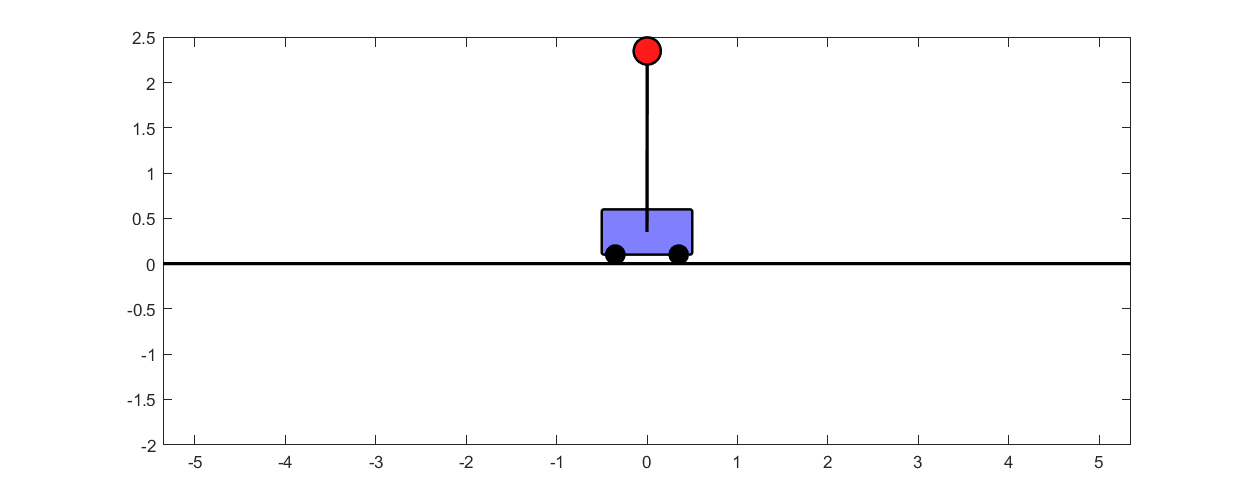

y0 = [1; pi+0.7; 0; 0];
tspan = 0:0.1:5;
% [t,y] = ode45(@(t,y) A*y,tspan,y0);
[t,y] = ode45(@(t,y) cartpole_dynamics(y, u(y), m1, m2, l)',tspan,y0);

for k=1:length(t)    
    drawpend(y(k,:),m2,m1,l);
    if k==1
        pause(1.0);
    end
end